# Chapter 6, Section 1 (Part 2)

Let's start this activity by presenting an alternate definition of the dot product, which we will find extremely useful. Let's start with an image. Note that we have marked each vector with its length, as in $||\textbf u||$, $||\textbf v||$, and $||\textbf u-\textbf v||$.

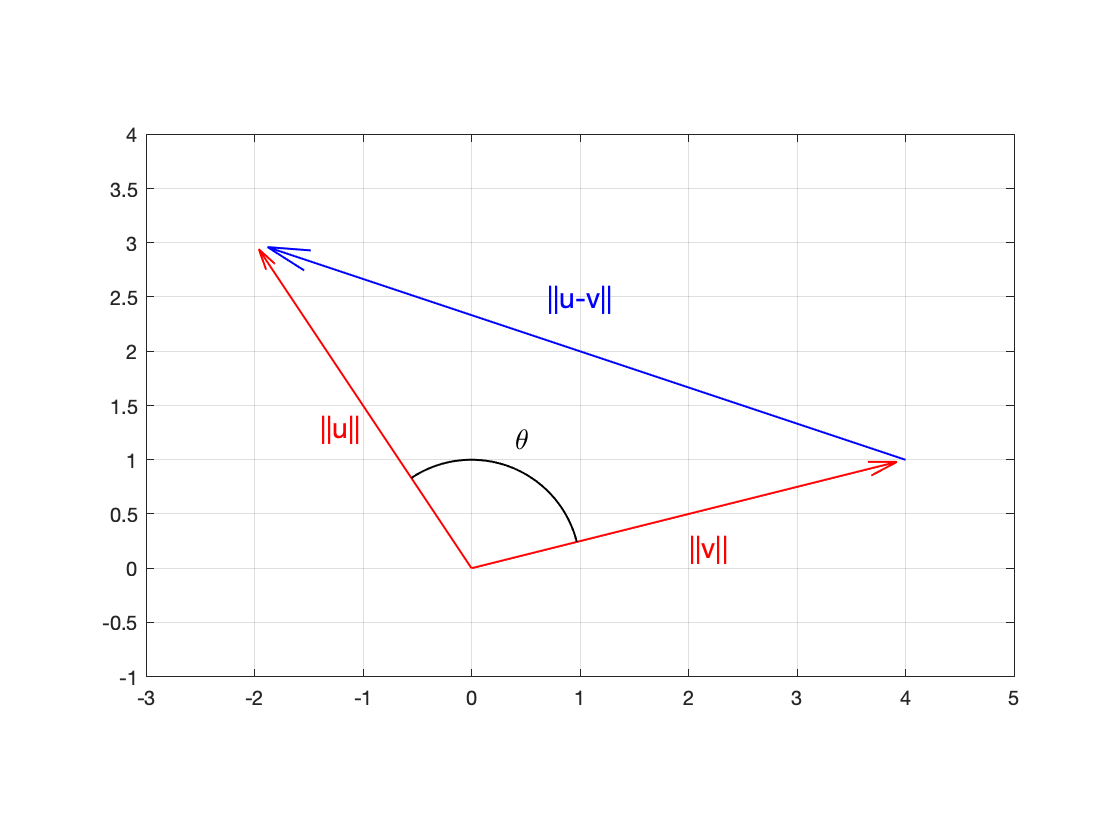

figure
quiver(0,0,-2,3,0.98,'LineWidth',1,'Color','r')
hold on
quiver(0,0,4,1,0.98,'LineWidth',1,'Color','r')
quiver(4,1,-6,2,0.98,'LineWidth',1,'Color','b')
t=linspace(atan2(1,4),atan2(3,-2));
plot(cos(t),sin(t),'Color','k','LineWidth',1)
text(0.4,1.2,'\theta','FontSize',14)
text(2,0.2,'||v||','FontSize',14,'Color','r')
text(-1.4,1.3,'||u||','FontSize',14,'Color','r')
text(0.7,2.5,'||u-v||','FontSize',14,'Color','b')
axis equal
axis([-3,5,-1,4])
grid on
hold off

Now, recall the law of cosines from trigonometry: $c^2=a^2+b^2-2ab\cos\theta$. If we apply this to this triangle, here is what we get.


$$||\textbf u-\textbf v||^2=||\textbf u||^2+||\textbf v||^2-2||\textbf u|| ||\textbf v||\cos\theta$$


Now, we can manipulate the left hand side of this equation with the properties we learned in our last activity. The first one we will use is the property $||\textbf u||^2=\textbf u\cdot\textbf u$. Therefore,


$$||\textbf u-\textbf v||^2=(\textbf u-\textbf v)\cdot(\textbf u-\textbf v)$$


Now we can use the distributive property of the dot product and write:


$$||\textbf u-\textbf v||^2=\textbf u\cdot\textbf u-\textbf u\cdot\textbf v-\textbf v\cdot\textbf u+\textbf v\cdot\textbf v$$


Now we can use the commutative property of the dot product and write:


$$\begin{array}{rcl}
||\textbf u-\textbf v||^2&=&\textbf u\cdot\textbf u-\textbf u\cdot\textbf v-\textbf u\cdot\textbf v+\textbf v\cdot\textbf v\\
||\textbf u-\textbf v||^2&=&\textbf u\cdot\textbf u-2\,\textbf u\cdot\textbf v+\textbf v\cdot\textbf v
\end{array}$$


Now we can use the property $||\textbf u||^2=\textbf u\cdot\textbf u$ again and write:


$$||\textbf u-\textbf v||^2=||\textbf u||^2-2\,\textbf u\cdot\textbf v+||\textbf v||^2$$


Now we can substitute this result into the left-hand side of our law of cosines equation above.


$$\begin{array}{rcl}
||\textbf u||^2-2\,\textbf u\cdot\textbf v+||\textbf v||^2&=&||\textbf u||^2+||\textbf v||^2-2||\textbf u|| ||\textbf v||\cos\theta\\
-2\,\textbf u\cdot\textbf v&=&-2||\textbf u|| ||\textbf v||\cos\theta\\
\textbf u\cdot\textbf v&=&||\textbf u|| ||\textbf v||\cos\theta
\end{array}$$


We have a valuable property for the dot product.

**The Dot Product: **Let $\textbf u$ and $\textbf v$ be vectors in $\mathbb R^n$. An alternate form for the dot product is


$$\textbf u\cdot\textbf v=||\textbf u|| ||\textbf v|| \cos\theta$$


where $\theta$ is the angle between the two vectors $\textbf u$ and $\textbf v$.

# Example #1

Find the angle between the two vectors $\textbf u=(4,1)^T$ and $\textbf v=(2,4)^T$.

**Solution:** Let's start with an image.

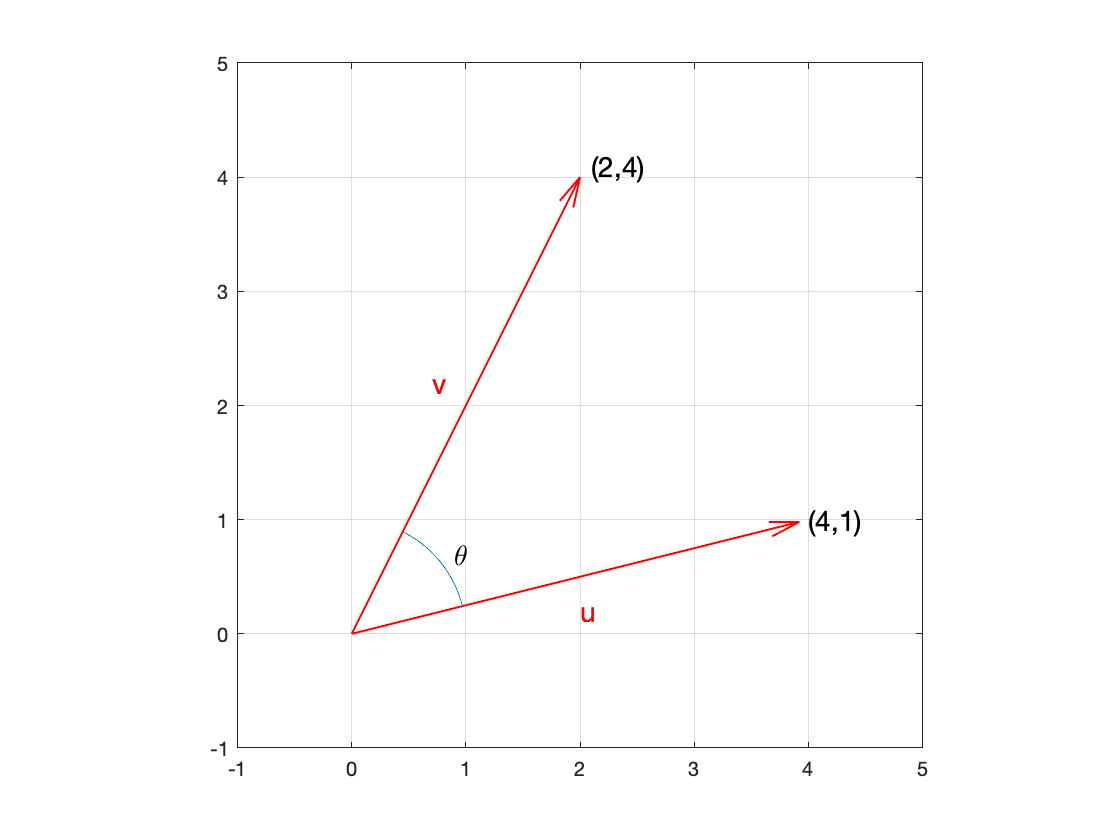

figure
u=[4;1];
v=[2;4];
quiver(0,0,u(1),u(2),0.98,'LineWidth',1,'Color','r')
hold on
quiver(0,0,v(1),v(2),0,'LineWidth',1,'Color','r')
t=linspace(atan2(1,4),atan2(4,2));
plot(cos(t),sin(t))
axis equal
axis([-1,5,-1,5])
text(4,1,'(4,1)','FontSize',14)
text(2.1,4.1,'(2,4)','FontSize',14)
text(0.9,0.7,'\theta','FontSize',14)
text(2,0.2,'u','FontSize',14,'Color','r')
text(0.7,2.2,'v','FontSize',14,'Color','r')
grid on
hold off

Now, your instructor used a protractor to measure the angle and found that it was about $50^\circ$. Now, let's use our new formula for the dot product to find the angle between these two vectors.


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&||\textbf u|| ||\textbf v||\cos\theta\\
\cos\theta&=&\frac{\textbf u\cdot\textbf v}{||\textbf u|| ||\textbf v||}
\end{array}$$


Now we will enter our vectors. Note that we enter them as $(4,1)$ and $(2,4)$ to save some space.


$$\begin{array}{rcl}
\cos\theta&=&\frac{(4,1)\cdot(2,4)}{||(4,1)||||(2,4)||}\\
\cos\theta&=&\frac{8+4}{\sqrt{4^2+1^2}\sqrt{2^2+4^2}}\\
\cos\theta&=&\frac{12}{\sqrt{17}\sqrt{20}}\\
\cos\theta&=&\frac{12}{2\sqrt{17}{\sqrt 5}}\\
\cos\theta&=&\frac{6}{\sqrt{85}
\end{array}$$


Therefore, the exact angle is:


$$\theta=\cos^{-1}\frac{6}{\sqrt{85}}$$


Matlab's **acos** command will return the angle in radians.

theta=acos(6/sqrt(85))

theta = 0.8622

Matlab's **acosd** command will return the angle in degrees.

theta=acosd(6/sqrt(85))

theta = 49.3987

Note that this agrees nicely with your instructor's estimate that the angle was $50^\circ$.

# Orthogonal Vectors

The word "Orthogonal" is similar to the word "Perpendicular." Let's look at an example.

# Example #2

Find the angle between the two vectors $\textbf u=(3,2)^T$ and $\textbf v=(-2,3)^T$. Are they "orthogonal?" Are they "perpendicular?"

**Solution:** Let's draw an image.

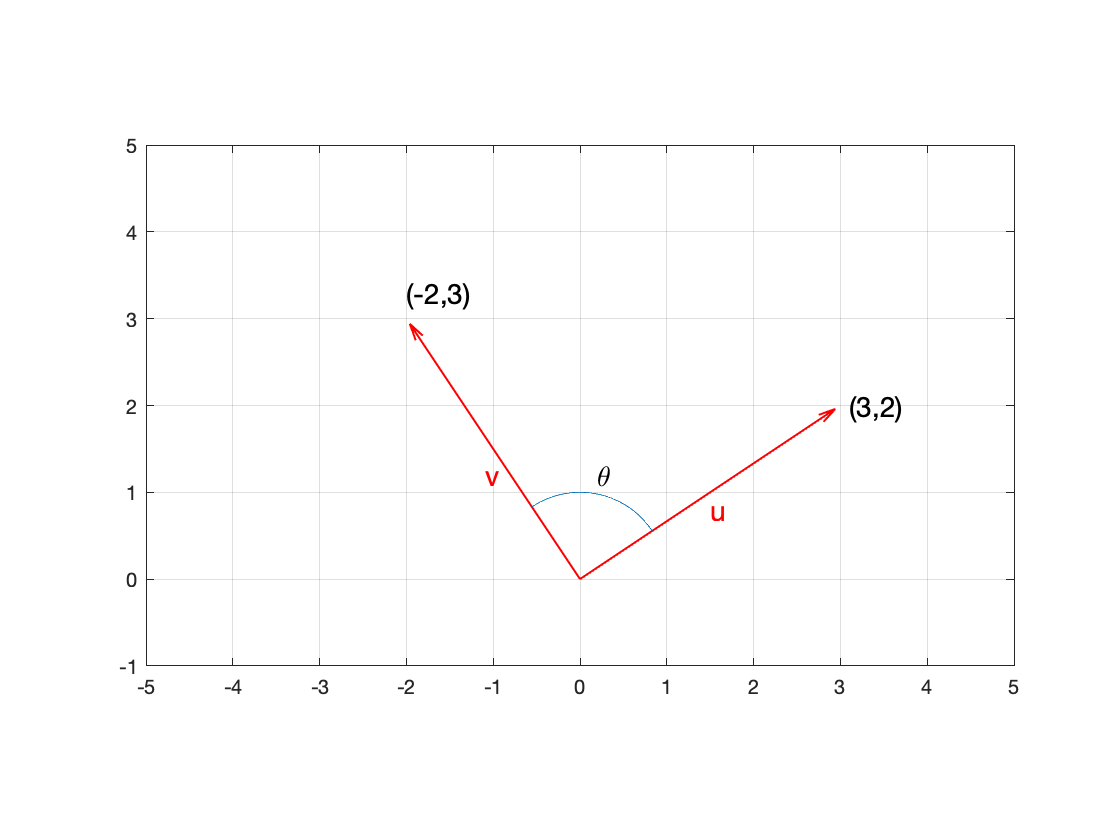

figure
u=[3;2];
v=[-2;3];
quiver(0,0,u(1),u(2),0.98,'LineWidth',1,'Color','r')
hold on
quiver(0,0,v(1),v(2),0.98,'LineWidth',1,'Color','r')
t=linspace(atan2(2,3),atan2(3,-2));
plot(cos(t),sin(t))
axis equal
axis([-5,5,-1,5])
text(3.1,2,'(3,2)','FontSize',14)
text(-2,3.3,'(-2,3)','FontSize',14)
text(0.2,1.2,'\theta','FontSize',14)
text(1.5,0.8,'u','FontSize',14,'Color','r')
text(-1.1,1.2,'v','FontSize',14,'Color','r')
grid on
hold off

It looks like the vectors are perpendicular to one another, so might the angle $\theta$ be equal to $90^\circ$? Let's use our new definition of the dot product to compute the angle.


$$\begin{array}{rcl}
\cos\theta&=&\frac{\text u\cdot\text v}{||\text u||||\text v||}\\
\cos\theta&=&\frac{(3,2)\cdot(-2,3)}{||(3,2)||||(-2,3)||}\\
\cos\theta&=&\frac{-6+6}{\sqrt{3^2+2^2}\sqrt{(-2)^2+3^2}}\\
\cos\theta&=&\frac{0}{\sqrt{13}\sqrt{13}}\\
\cos\theta&=&0
\end{array}$$


Note that we can check our calculations with Matlab as follows:

u=[3;2];
v=[-2;3];
dot(u,v)/(norm(u)*norm(v))

ans = 0

Same as our hand-calculated result. Now, Because $\cos\theta=0$, this means that the angle is $\theta=\pi/2$, or in degrees, $\theta=90^\circ$. We can verify this with Matlab. If we use the Symbolic Toolbox, we get an exact answer in radians.

theta=acos(sym(0))

$$theta = \frac{\pi }{2}$$

And Matlab's **acosd** returns a numerical answer in degrees.

theta=acosd(0)

theta = 90

Thus, because we've shown that the angle between the two vectors is $90^\circ$, the vectors $\textbf u=(3,2)^T$ and $\textbf v=(-2,3)^T$ are "orthogonal" (perpendicular).

**Important Thing to Note:** Consider the formula:


$$\begin{array}{rcl}
\cos\theta&=&\frac{\textbf u\cdot\textbf v}{||\textbf u|| ||\textbf v||}
\end{array}$$


If the lengths of the vectors are nonzero, then the denominator is nonzero. Secondly, if the numerator is zero (i.e., $\textbf u\cdot\textbf v=0$), then $\cos\theta=0$ and the vectors are perpendicular (orthogonal) to one another. 

**Definition: **Two vectors $\textbf u$ and $\textbf v$ are orthogonal (perpendicular) if and only if $\textbf u\cdot\textbf v=0$.

# Example #3

Are the vectors $\textbf u=(1,1,-1)^T$ and $\textbf v=(1,0,1)^T$ orthogonal?

**Solution:** If the dot product is zero, then they are orthogonal. Let's compute the dot product.


$$\begin{array}{rcl}
\textbf u\cdot\textbf v&=&\pmatrix{1\cr 1\cr -1}\cdot\pmatrix{1\cr 0\cr 1}\\
\textbf u\cdot\textbf v&=&1+0-1\\
\textbf u\cdot\textbf v&=&0
\end{array}$$


The dot product is zero, so they are orthogonal. Let's visualize this result.

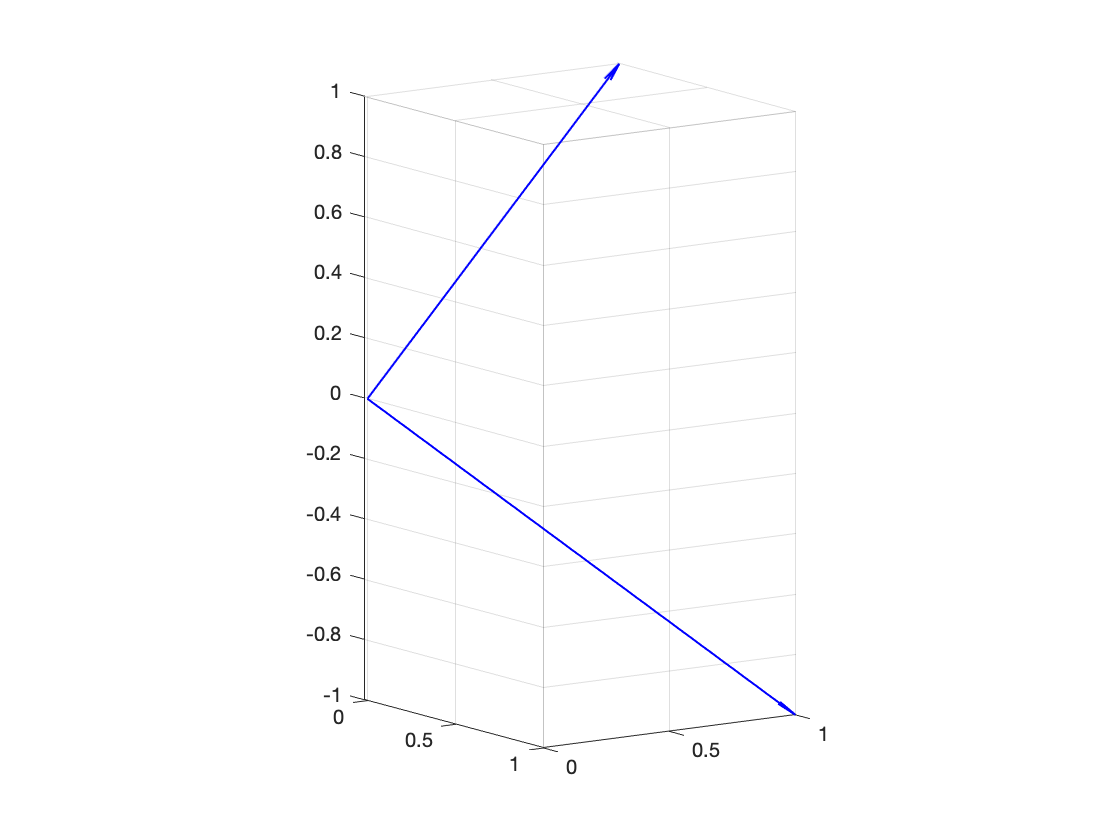

figure
u=[1;1;-1];
v=[1;0;1];
quiver3(0,0,0,u(1),u(2),u(3),0,'LineWidth',1,'Color','b')
hold on
quiver3(0,0,0,v(1),v(2),v(3),0,'LineWidth',1,'Color','b')
axis equal
view([34.97 -10.85])
hold off

Have fun rotating the image until you get what you think is the best view that shows they are orthogonal (perpendicular).